# Train SVM Classifier

Load Fisher's iris data set. Remove the sepal lengths and widths and all observed setosa irises.

load fisheriris
inds = ~strcmp(species,'setosa');
X = meas(inds,3:4);
y = species(inds);

Train an SVM classifier using the processed data set.

SVMModel = fitcsvm(X,y)

SVMModel =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 100
                    Alpha: [24×1 double]
                     Bias: -14.4149
         KernelParameters: [1×1 struct]
           BoxConstraints: [100×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [100×1 logical]
                   Solver: 'SMO'


  Properties, Methods


`SVMModel` is a trained `ClassificationSVM` classifier. Display the properties of `SVMModel`. For example, to determine the class order, use dot notation.

classOrder = SVMModel.ClassNames

classOrder = 2×1 cell array
    {'versicolor'}
    {'virginica' }


The first class (`'versicolor'`) is the negative class, and the second (`'virginica'`) is the positive class. You can change the class order during training by using the `'ClassNames'` name-value pair argument.

Plot a scatter diagram of the data and circle the support vectors.

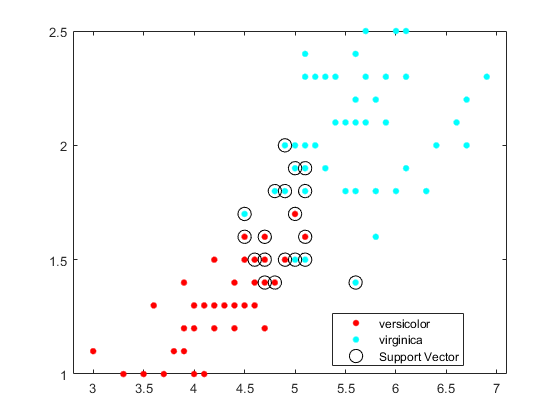

sv = SVMModel.SupportVectors;
figure
gscatter(X(:,1),X(:,2),y)
hold on
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
legend('versicolor','virginica','Support Vector')
hold off

The support vectors are observations that occur on or beyond their estimated class boundaries.

You can adjust the boundaries (and, therefore, the number of support vectors) by setting a box constraint during training using the `'BoxConstraint'` name-value pair argument.

*Copyright 2015 The MathWorks, Inc.*